6.1 Design and measurement of an FIR filter

Design an FIR filter with a low-pass characteristic using the firpm command in MATLAB that meets the following requirements: 

Cutoff frequency 5 kHz 

Stop frequency 6 kHz 

Passband ripple 2 dB 

Stopband attenuation 30 dB

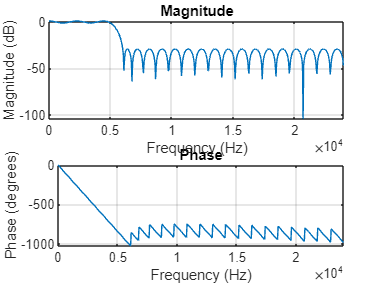

rp = 2;            % Passband ripple in dB 
rs = 30;           % Stopband ripple in dB
fs = 48000;        % Sampling frequency
f  = [5000 6000];  % Cutoff frequencies
a  = [1 0];        % Desired amplitudes

% Converting the deviations to linear units
dev = [(10^(rp/20)-1)/(10^(rp/20)+1) 10^(-rs/20)]; 
[n,fo,ao,w] = firpmord(f,a,dev,fs);
b = firpm(n,fo,ao,w);
freqz(b,1,[],fs)

6.3 Design of a Butterworth IIR filter

Design a Butterworth IIR filter using the butter command in MATLAB with a filter order N = 4 and a cutoff frequency of fc = 12 kHz and plot the frequency response in MATLAB.

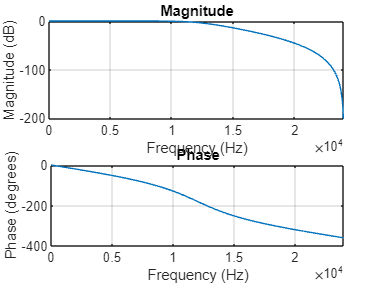

fc = 12000;
fs = 48000;
N  = 4;

[b,a] = butter(N,fc/(fs/2));

freqz(b,a,[],fs)

6.4 Design of a Chebyshev 1 IIR filter 

Design a Chebyshev 1 IIR filter using the cheby1 command in MATLAB with a filter order N = 4, a cutoff frequency of fc = 4 kHz and a passband ripple of 2 dB and plot the frequency response in MATLAB. Compare the transfer function with that of the Butterworth filter. 

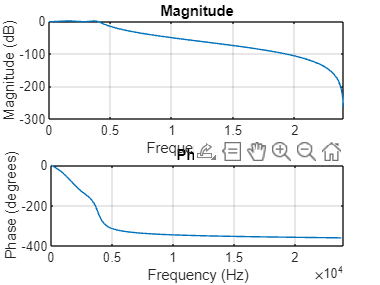

fc = 4000;
fs = 48000;
N  = 4;
Rp = 2;

[b,a] = cheby1(N,Rp,fc/(fs/2));

freqz(b,a,[],fs)

6.5 Supplementary task 

Design a Chebyshev 1 IIR filter using the cheby1 command in MATLAB with a filter order N = 10, a cutoff frequency of fc = 4 kHz and a passband ripple of 2 dB and plot the frequency response in MATLAB. Compare the frequency response with the 4th order Chebyshev 1 filter designed above.

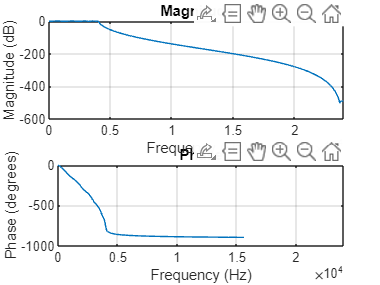

fc = 4000;
fs = 48000;
N  = 10;
Rp = 2;

[b,a] = cheby1(N,Rp,fc/(fs/2));

freqz(b,a,[],fs)